%% QPSK Modulation with Slightly Increased Rayleigh Noise and Multi-Path Fading
% This script simulates QPSK modulation with realistic multi-path fading 
% (802.11 Wi-Fi), Rayleigh noise, improved filtering, and BER calculations.

%% Load the Original Audio File
[audioIn, fs] = audioread('input_voice.wav');  % Sampling rate
audioIn = audioIn(:, 1);  % Use only one channel if stereo
audioIn = audioIn / max(abs(audioIn));  % Normalize input to [-1, 1]

disp('Playing Original Audio...');

Playing Original Audio...


sound(audioIn, fs);
pause(length(audioIn)/fs + 1);

%% QPSK Modulation
% Convert audio to binary
scaledSignal = uint8((audioIn + 1) * 127);
bits = reshape(de2bi(scaledSignal, 8, 'left-msb')', [], 1);

% Prepare for QPSK modulation
M = 4;  % QPSK modulation order
padLength = mod(-length(bits), log2(M));  % Pad bits to match modulation order
if padLength > 0
    bits = [bits; zeros(padLength, 1)];
end

% Perform QPSK modulation
symbols = bi2de(reshape(bits, log2(M), [])', 'left-msb');
modulatedSignal = pskmod(symbols, M, pi/4);
modulatedSignal = modulatedSignal / max(abs(modulatedSignal)); % Normalize

%% Apply Multi-Path Rayleigh Fading Channel (802.11 Wi-Fi Simulation)
multiPathChannel = comm.RayleighChannel(...
    'SampleRate', fs, ...
    'PathDelays', [0 1e-8 2e-8], ... % Negligible path delays
    'AveragePathGains', [0 -0.1 -0.2], ... % Minimal path attenuation
    'MaximumDopplerShift', 0.01, ... % Very low Doppler shift (static channel)
    'NormalizePathGains', true);

% Pass signal through Rayleigh channel
fadedSignal = multiPathChannel(modulatedSignal);

%% Add Slightly Increased Rayleigh Noise
% Generate Rayleigh noise
noiseScale = 0.06; % Slightly increased noise scale
rayleighNoise = raylrnd(noiseScale, size(fadedSignal));
complexNoise = rayleighNoise .* exp(1j * 2 * pi * rand(size(fadedSignal)));

% Scale noise to achieve desired SNR
signalPower = mean(abs(fadedSignal).^2);
noisePower = mean(abs(complexNoise).^2);
desiredSNR_dB = 30;  % Slightly reduced SNR for minimal noise presence
desiredSNR_linear = 10^(desiredSNR_dB/10);
scaleFactor = sqrt(signalPower / (noisePower * desiredSNR_linear));
scaledNoise = complexNoise * scaleFactor;

% Add scaled noise to the faded signal
noisySignal = fadedSignal + scaledNoise;
noisySignal = noisySignal / max(abs(noisySignal)); % Normalize

%% QPSK Demodulation
% Demodulate the noisy signal
receivedSymbols = pskdemod(noisySignal, M, pi/4);
receivedBits = reshape(de2bi(receivedSymbols, log2(M), 'left-msb')', [], 1);

% Convert bits back to audio
expectedBits = length(audioIn) * 8;
receivedBits = receivedBits(1:expectedBits);
receivedBytes = reshape(receivedBits, 8, [])';
receivedInts = bi2de(receivedBytes, 'left-msb');
audioNoisy = (double(receivedInts) / 127) - 1;

% Normalize the noisy audio
audioNoisy = audioNoisy / max(abs(audioNoisy));

disp('Playing Noisy Audio (After QPSK and Multi-Path Fading)...');

Playing Noisy Audio (After QPSK and Multi-Path Fading)...


sound(audioNoisy, fs);
pause(length(audioNoisy)/fs + 1);

%% Improved Noise Removal using Low-Pass Filtering
fc = 4000;  % Cut-off frequency for improved filtering
Wn = fc / (fs / 2);  % Normalized frequency
[b, a] = butter(8, Wn, 'low');  % 8th-order Butterworth filter

audioFiltered = filter(b, a, audioNoisy);
audioFiltered = audioFiltered / max(abs(audioFiltered)); % Normalize

disp('Playing Denoised Audio...');

Playing Denoised Audio...


sound(audioFiltered, fs);
pause(length(audioFiltered)/fs + 1);

%% Calculate Bit Error Rate (BER)
% Compare transmitted bits and received bits
bitErrors = sum(bits ~= receivedBits);
totalBits = length(bits);
BER = bitErrors / totalBits;

fprintf('\n--- Bit Error Rate (BER) Calculation ---\n');


--- Bit Error Rate (BER) Calculation ---


fprintf('Total Bits Transmitted: %d\n', totalBits);

Total Bits Transmitted: 1209600


fprintf('Bit Errors: %d\n', bitErrors);

Bit Errors: 940276


fprintf('Bit Error Rate (BER): %.9f\n', BER);

Bit Error Rate (BER): 0.777344577


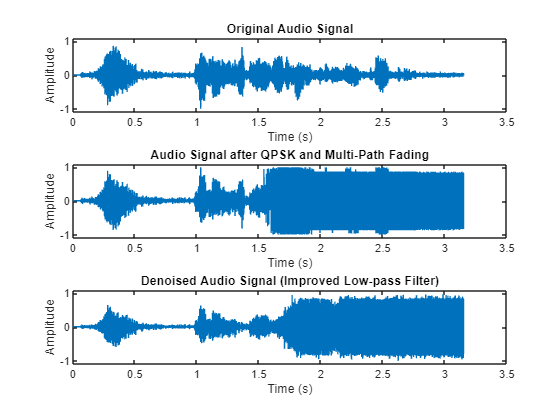


%% Plot the Signals for Comparison
t = (0:length(audioIn)-1) / fs;  % Time vector

figure;
subplot(3,1,1);
plot(t, audioIn);
title('Original Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1.1 1.1]);

subplot(3,1,2);
plot(t, audioNoisy);
title('Audio Signal after QPSK and Multi-Path Fading');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1.1 1.1]);

subplot(3,1,3);
plot(t, audioFiltered);
title('Denoised Audio Signal (Improved Low-pass Filter)');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-1.1 1.1]);


%% Save the Processed Audio Files
audiowrite('noisy_audio.wav', audioNoisy, fs);
audiowrite('denoised_audio.wav', audioFiltered, fs);

%% Debug Information
fprintf('\n--- Debug Information ---\n');


--- Debug Information ---


fprintf('Original signal length: %d\n', length(audioIn));

Original signal length: 151200


fprintf('Noisy signal length: %d\n', length(audioNoisy));

Noisy signal length: 151200


fprintf('Filtered signal length: %d\n', length(audioFiltered));

Filtered signal length: 151200


fprintf('SNR (dB): %.2f\n', desiredSNR_dB);

SNR (dB): 30.00


fprintf('Noise scale: %.2f\n', noiseScale);

Noise scale: 0.06



disp('Audio processing complete. Files saved.');

Audio processing complete. Files saved.
